# GradCam

**載入模型與影像(Load Model & Image)**

net = trainedNetwork_1;
img = imread("86_AL.jpg");

**影像辨識(Image Classify)**

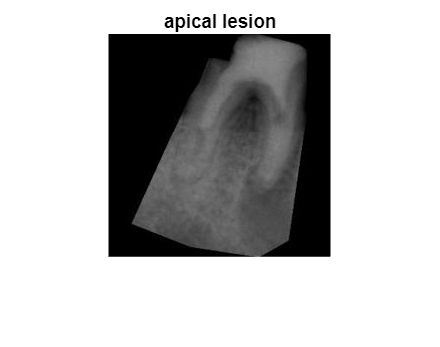

inputSize = net.Layers(1).InputSize(1:2);
re_img = imresize(img,inputSize);
figure,imshow(re_img)

[label,scores] = classify(net,re_img);
title(char(label))

**影像可視化(Image Occlusion)**

map = gradCAM(net,re_img,label);

**顯示熱圖(Show ScoreMap)**

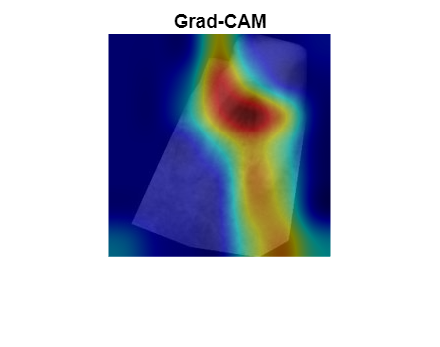

figure,imshow(re_img);
hold on;
imagesc(map,'AlphaData',0.5);
colormap jet
hold off;
title("Grad-CAM");